cd('/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220519_AchsensorHEK_001')
excelname = '20220519_AchsensorHEK_001.xlsx'

excelname = '20220519_AchsensorHEK_001.xlsx'

load('20220519_AchsensorHEK_001_Analysis2022-09-09.mat')

FLIM_posthoc_analysis_dendrite_HEK_cell

[a, b]=size(lft1)

a = 109

b = 4

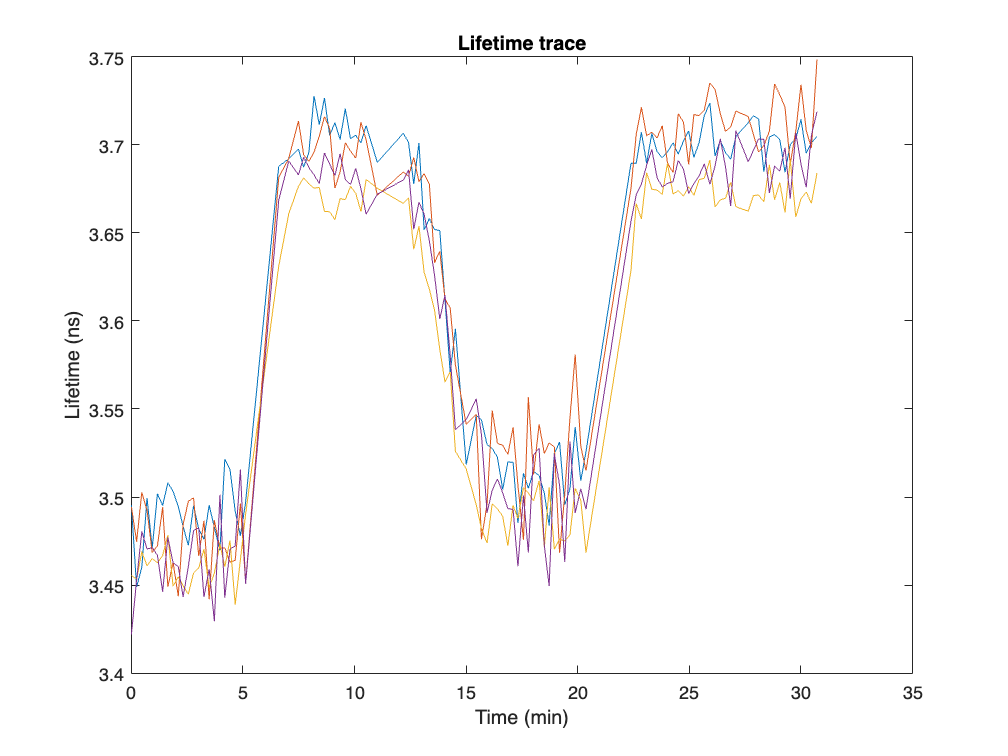

figure
for i=1:b
    plot(AcqTime1(1:a),lft1(:,i))
    hold on
end
title('Lifetime trace')
ylabel('Lifetime (ns)')
xlabel('Time (min)')

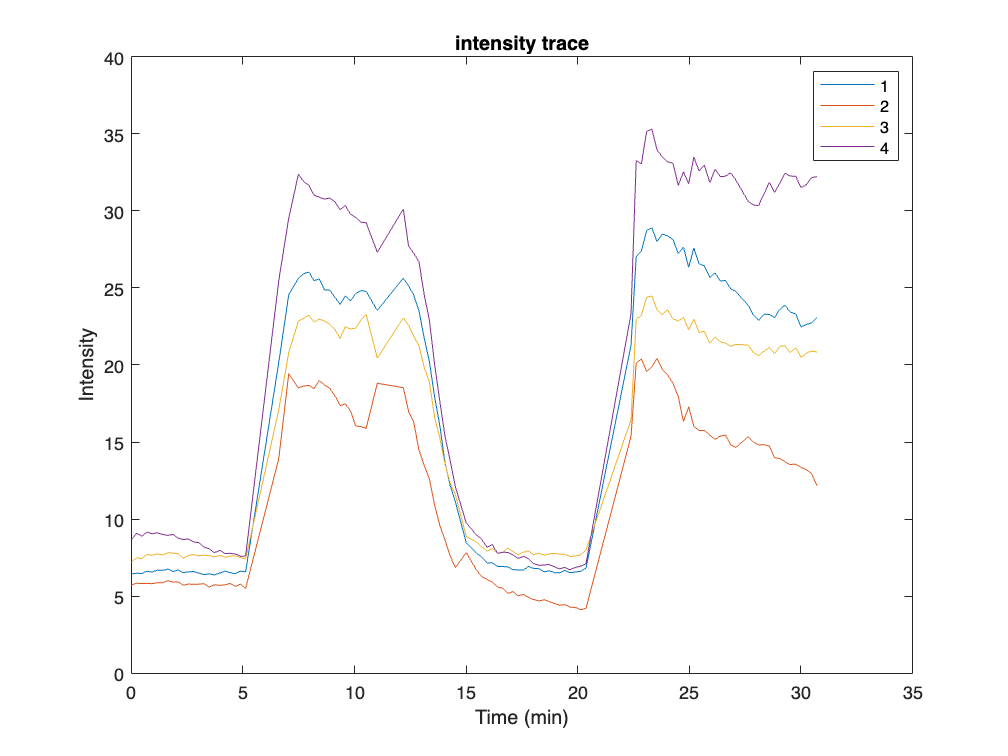

figure
for i=1:b
    plot(AcqTime1(1:a),intensity1(:,i))
    hold on
end

title('intensity trace')
ylabel('Intensity')
xlabel('Time (min)')
legend('1','2','3','4')


intensity_baselines = intensity_baseline_increase_all(:,1)

intensity_baselines =    22.0413
   17.9490
   40.5650
   32.5422
   26.9537
   58.9828
   25.8289
   26.7132


intensity_changes = intensity_baseline_increase_all(:,2:end)

intensity_changes =     1.7069   32.9204
    1.5384   28.5348
    3.9911   49.4964
   31.7382   39.0012
   33.1358   34.8761
   54.0768   55.3177
    8.5672    8.3795
   33.9054   41.0879


intensity_change_ratio = intensity_changes./intensity_baselines

intensity_change_ratio =     0.0774    1.4936
    0.0857    1.5898
    0.0984    1.2202
    0.9753    1.1985
    1.2294    1.2939
    0.9168    0.9379
    0.3317    0.3244
    1.2692    1.5381


figure
for i=1:size(lft_baseline_increase_all, 2)-1
    scatter(zeros(1,b)+i, lft_baseline_increase_all(:,i+1))
    hold on
end

Error using scatter
X and Y must be vectors of the same length, matrices of the same size, or
a combination of a vector and a matrix where the length of the vector
matches either the number of rows or columns of the matrix.

title('Lifetime change (0=baseline; 1=1st flow-in; 2=wash out; 3=2nd flow-in )')
ylabel('Lifetime increase (ns)')
hold off

figure
for i=1:size(intensity_change_ratio, 2)
    scatter(zeros(1,b)+i, intensity_change_ratio(:,i))
    hold on
end
title('Intensity change (0=baseline; 1=1st flow-in; 2=wash out; 3=2nd flow-in )')
ylabel('Intensity increase (dF/F_0)')
hold off

save('analyzed_data_and_plots.mat')

cd('/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220518_AchsensorHEK003')
excelname = '20220518_AchsensorHEK003.xlsx'

excelname = '20220518_AchsensorHEK003.xlsx'

load('20220518_AchsensorHEK003_Analysis2022-09-10.mat')

FLIM_posthoc_analysis_dendrite_HEK_cell

[a, b]=size(lft1)

a =    123


b =      2


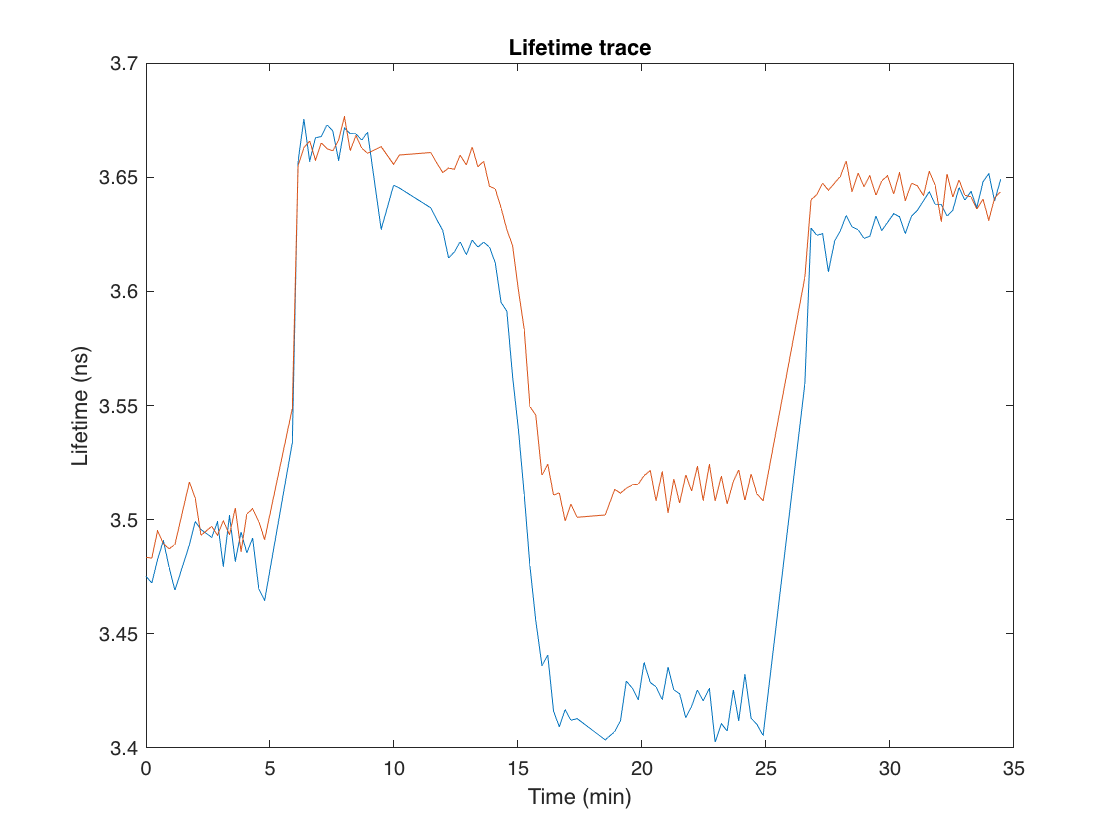

figure
for i=1:b
    plot(AcqTime1(1:a),lft1(:,i))
    hold on
end
title('Lifetime trace')
ylabel('Lifetime (ns)')
xlabel('Time (min)')

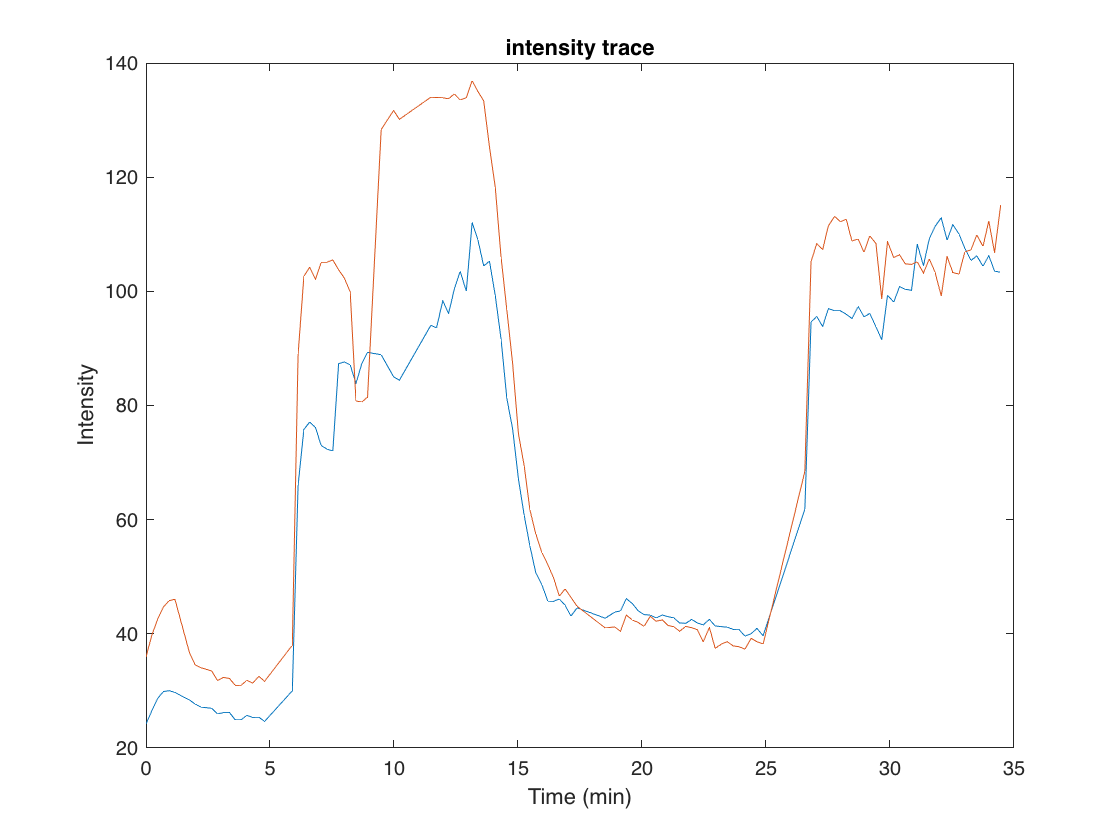

figure
for i=1:b
    plot(AcqTime1(1:a),intensity1(:,i))
    hold on
end

title('intensity trace')
ylabel('Intensity')
xlabel('Time (min)')

[a, b]=size(lft2)

a =    126


b =      2


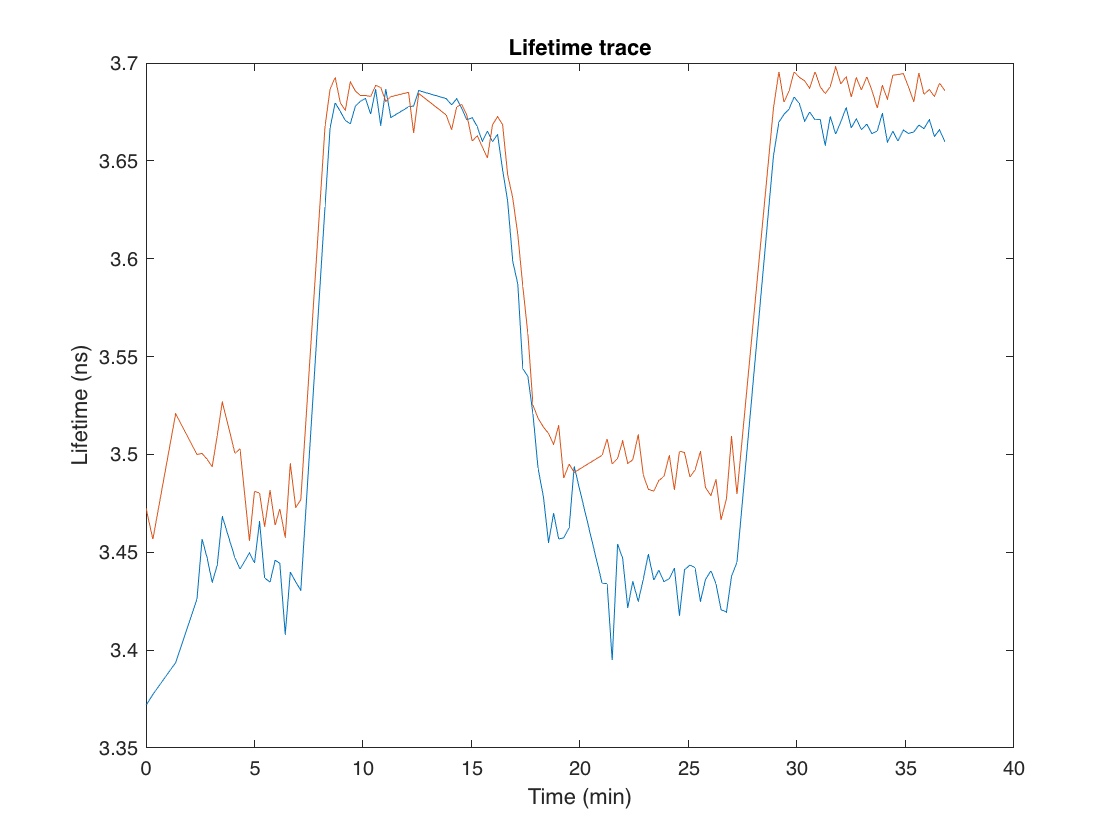

figure
for i=1:b
    plot(AcqTime2(1:a),lft2(:,i))
    hold on
end
title('Lifetime trace')
ylabel('Lifetime (ns)')
xlabel('Time (min)')

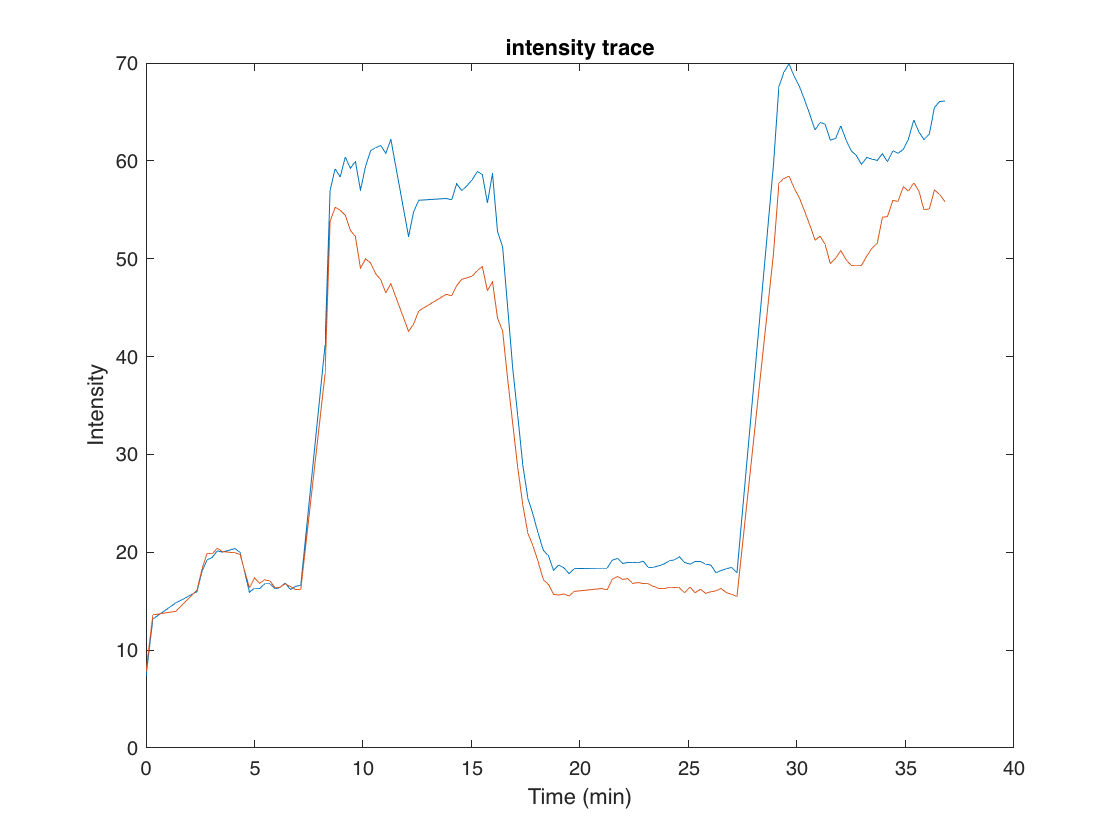

figure
for i=1:b
    plot(AcqTime2(1:a),intensity2(:,i))
    hold on
end

title('intensity trace')
ylabel('Intensity')
xlabel('Time (min)')

intensity_baselines = intensity_baseline_increase_all(:,1)

intensity_baselines =   26.771784030713903
  35.757793243439174
  16.856213664018139
  17.062283540566629


intensity_changes = intensity_baseline_increase_all(:,2:end)

intensity_changes = 	1.0e+02 *

   0.032623803275502   0.672686337712843   0.852738801759282   0.861252612139768
   0.103021241119327   0.982501268667537   1.011468210816297   0.794801719323887
   0.035249727171682   0.453463135385091   0.420398902320858   0.530518242440198
   0.033570799977289   0.381914920797138   0.321324305910407   0.413897121444388


intensity_change_ratio = intensity_changes./intensity_baselines

intensity_change_ratio =    0.121858906519170   2.512669073309064   3.185214705082702   3.217016135912707
   0.288108498245287   2.747656327611339   2.828665079889629   2.222737051788612
   0.209120078057196   2.690183836202011   2.494029268377487   3.147315601324279
   0.196754437338196   2.238357602539614   1.883243266626291   2.425801449497201


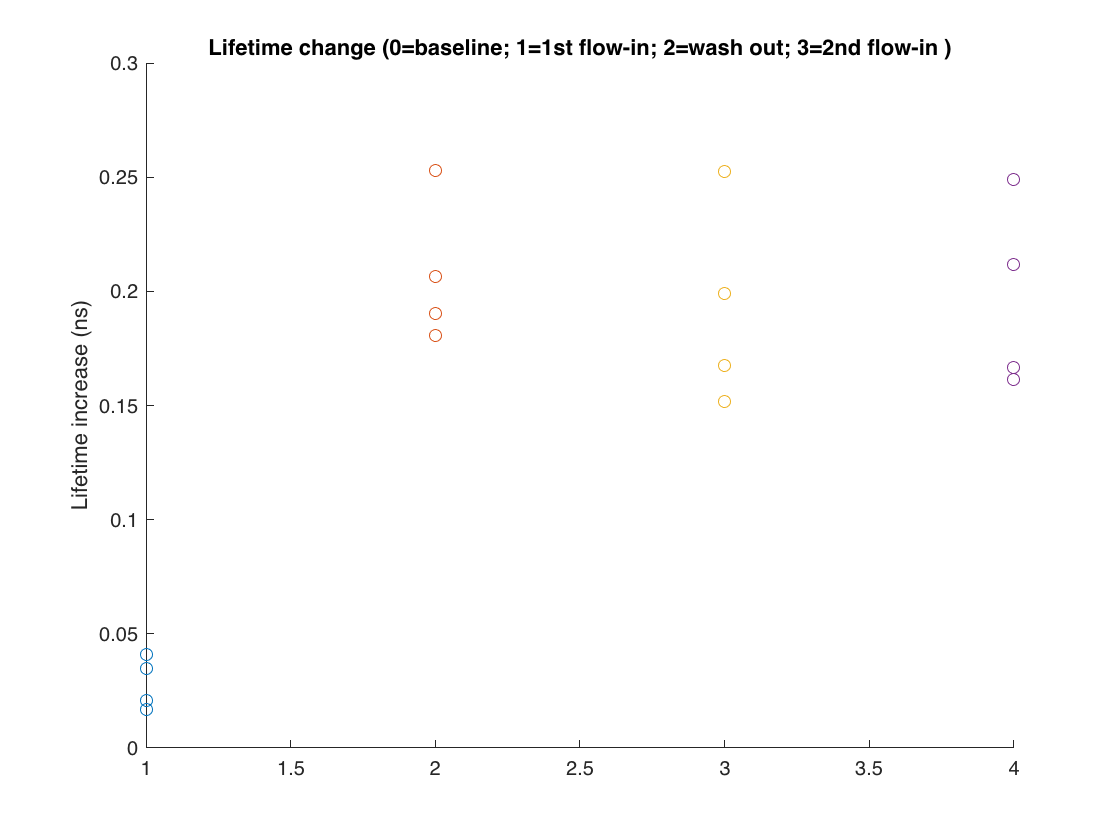

figure
for i=1:size(lft_baseline_increase_all, 2)-1
    scatter(zeros(1,size(lft_baseline_increase_all, 1))+i, lft_baseline_increase_all(:,i+1))
    hold on
end
title('Lifetime change (0=baseline; 1=1st flow-in; 2=wash out; 3=2nd flow-in )')
ylabel('Lifetime increase (ns)')
hold off

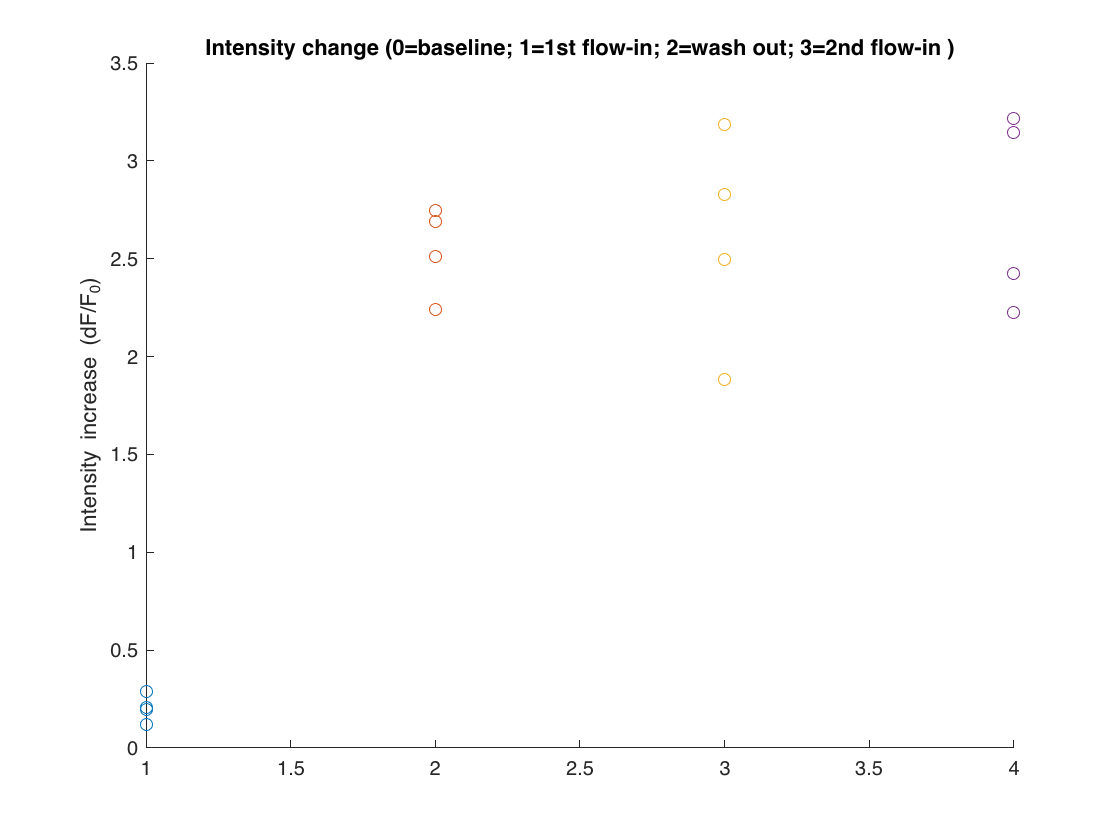

figure
for i=1:size(intensity_change_ratio, 2)
    scatter(zeros(1,size(lft_baseline_increase_all, 1))+i, intensity_change_ratio(:,i))
    hold on
end
title('Intensity change (0=baseline; 1=1st flow-in; 2=wash out; 3=2nd flow-in )')
ylabel('Intensity increase (dF/F_0)')
hold off

save('analyzed_data_and_plots.mat')